
Single objective optimization:
3 Variables

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible
Tempo de acomodação (TAC): 29.49 s
Overshoot: 71.25%
Erro para cima em regime: -0.0021
Tempo de acomodação (TAC): 17.54 s
Overshoot: 89.35%
Erro para cima em regime: -0.0013
Tempo de acomodação (TAC): 32.46 s
Overshoot: 76.08%
Erro para cima em regime: -0.0004
O sistema não estabilizou (TAC máximo: 49.00 s)
Overshoot: 100.00%
Erro para baixo em regime: 10.0000
Tempo de acomodação (TAC): 48.83 s
Overshoot: 83.70%
Erro para baixo em regime: 0.0265
O sistema não estabilizou (TAC máximo: 49.00 s)
Overshoot: 100.00%
Erro para baixo em regime: 1.0512
Tempo de acomodação (TAC): 13.32 s
Overshoot: 87.15%
Erro para cima em regime: -0.0013
Tempo de acomodação (TAC): 49.00 s
Overshoot: 100.00%
Erro para baixo em regime: 10.0000
Tempo de acomodação (TAC): 9.48 s
Overshoot: 76.15%
Erro para

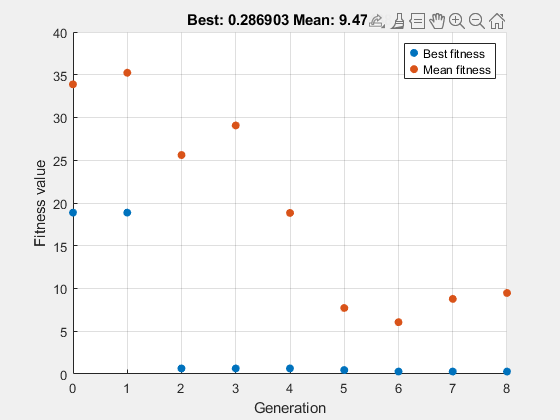

% É necessário a simulação, no Simulink, da planta sem nenhum tipo de controle para rodar o código abaixo
function otimizar_pid()
    % Carrega o modelo Simulink
    modelo_planta = 'modelo_planta'; % Substitua pelo nome real do seu modelo
    load_system(modelo_planta);
    
    % Define a função de avaliação para o Algoritmo Genético
    fitness_func = @(x) avaliar_pid(x(1), x(2), x(3), modelo_planta);
    
     % Define a população inicial como [1 1 1]
    populacao_inicial = [1,0,0];  % linha única com Kp=1, Ki=1, Kd=1

    % Configuração do algoritmo genético
     opts = optimoptions('ga', ...
        'Display', 'iter', ...
        'MaxGenerations', 8, ...
        'PopulationSize', 10, ...
        'InitialPopulationMatrix', populacao_inicial, ...
        'PlotFcn', {@gaplotbestf}, ...
        'OutputFcn', @salvar_media_fitness);  
    
    % Limites para os ganhos PID
    limites_min = [0.001, 0.001, 0];
    limites_max = [5, 5, 5];
    
    % Executa a otimização
    melhores_parametros = ga(fitness_func, 3, [], [], [], [], limites_min, limites_max, [], opts);
    
    % Exibe os melhores parâmetros encontrados
    fprintf('\n\nMelhores parâmetros encontrados: Kp = %.4f, Ki = %.4f, Kd = %.4f\n', ...
            melhores_parametros(1), melhores_parametros(2), melhores_parametros(3));
    
    % Aplica os melhores parâmetros ao modelo Simulink
    set_param([modelo_planta, '/PID Controller'], ...
              'P', num2str(melhores_parametros(1)), ...
              'I', num2str(melhores_parametros(2)), ...
              'D', num2str(melhores_parametros(3)));
    
    % Salva e fecha o modelo Simulink
    save_system(modelo_planta);
    %close_system(modelo_planta, 0); % Habilite se quiser fechar o modelo após salvar
end

function nota = avaliar_pid(Kp, Ki, Kd, modelo_planta)

    % Aplica os ganhos ao controlador PID no modelo Simulink
    set_param([modelo_planta, '/PID Controller'], ...
              'P', num2str(Kp), 'I', num2str(Ki), 'D', num2str(Kd));

    % Executa a simulação
    out = sim(modelo_planta);

    % Coleta sinais do escopo
    tempo  = out.scope.time;
    entr   = out.scope.signals.values(:,1);  % sinal de entrada (referência)
    saida  = out.scope.signals.values(:,2);  % resposta do sistema

    % Valor final esperado da saída (último valor)
    valor_final_saida = saida(end);
    valor_final_entrada = entr(end);

    % Faixa de tolerância de 2% em torno do valor final (critério para regime)
    tolerancia = 0.02;
    fabaixo = valor_final_saida * (1 - tolerancia);
    facima  = valor_final_saida * (1 + tolerancia);

    % Determina o instante de início da resposta (para evitar erro em t = 0)
    inicio = 1;
    if saida(1) == 0
        for i = 1:length(saida)
            if saida(i) ~= 0
                inicio = i;
                break;
            end
        end
    end

    % ===== TEMPO DE ACOMODAÇÃO (TAC) =====
    % Percorre os dados procurando o ponto onde a resposta entra e permanece na faixa de ±2%
    postac = 0;
    dentroFaixa = false;
    for i = 1:length(saida)
        if ~dentroFaixa
            if saida(i) >= fabaixo && saida(i) <= facima
                postac = i;
                dentroFaixa = true;
            end
        else
            if saida(i) < fabaixo || saida(i) > facima
                dentroFaixa = false;
            end
        end
    end

    % Calcula o TAC como o tempo entre início da resposta e acomodação
    if dentroFaixa && postac > 0
        TAC = tempo(postac) - tempo(inicio);
        fprintf('Tempo de acomodação (TAC): %.2f s\n', TAC);
    else
        TAC = tempo(end) - tempo(inicio);  % usa tempo total como penalização
        fprintf('O sistema não estabilizou (TAC máximo: %.2f s)\n', TAC);
    end

    % ===== OVERSHOOT (ULTRAPASSAGEM) =====
    % Calcula o pico de resposta dentro da fase transitória (até o TAC)
    if postac > 0
        pico = max(saida(1:postac));
    else
        pico = max(saida);  
    end

    if pico > valor_final_entrada
        over = (pico - valor_final_entrada) / valor_final_entrada * 100;
        if over > 100
            over = 100;
            fprintf('Overshoot: %.2f%%\n', over);
        else 
            fprintf('Overshoot: %.2f%%\n', over);
        end
    else
        over = 0;
        fprintf('Não há Overshoot\n');
    end

    % ===== ERRO ESTACIONÁRIO =====
    % Diferença entre a entrada final e a saída final
    erro = valor_final_entrada - valor_final_saida;
    erro_tolerancia = 1e-5;

    if abs(erro) > erro_tolerancia
        if abs(erro) > 10
            erro = 10;
            if erro > 0
                fprintf('Erro para baixo em regime: %.4f\n', erro);
            else
                fprintf('Erro para cima em regime: %.4f\n', erro);
            end
        else
            if erro > 0
                fprintf('Erro para baixo em regime: %.4f\n', erro);
            else
                fprintf('Erro para cima em regime: %.4f\n', erro);
            end
        end
    else
        erro = 0;
        fprintf('Erro em regime desprezível (≈0)\n');
    end

    % ===== FUNÇÃO DE CUSTO (NOTA) =====
    % Define metas desejadas para cada métrica
    meta_TAC  = 1.0;   % segundos
    meta_over = 0.0;   % porcentagem
    meta_erro = 0.0;   % ideal sem erro estacionário

    % Nota baseada na soma das distâncias às metas
    nota = 0.05*(abs(erro - meta_erro)) + 0.35*(abs(TAC - meta_TAC)) + 0.60*(abs(over - meta_over));
end

function [state, options, optchanged] = salvar_media_fitness(options, state, flag)
    persistent dados_geracoes;
    optchanged = false;

    if strcmp(flag, 'init')
        dados_geracoes = [];  % zera os dados no início

    elseif strcmp(flag, 'iter')
        media_geracao = mean(state.Score);
        melhor_geracao = min(state.Score);
        dados_geracoes(end+1, :) = [melhor_geracao, media_geracao];

    elseif strcmp(flag, 'done')
        nome_arquivo = 'fitness_geracoes.xlsx';
        cabecalho = {'Geracao', 'MelhorNota', 'MediaNota'};
        geracoes = (1:size(dados_geracoes,1))';
        tabela = [geracoes, dados_geracoes];
        xlswrite(nome_arquivo, [cabecalho; num2cell(tabela)]);

        fprintf('\n✅ Dados de fitness salvos em %s\n', nome_arquivo);

    end
end

% Executa a otimização automaticamente
otimizar_pid();